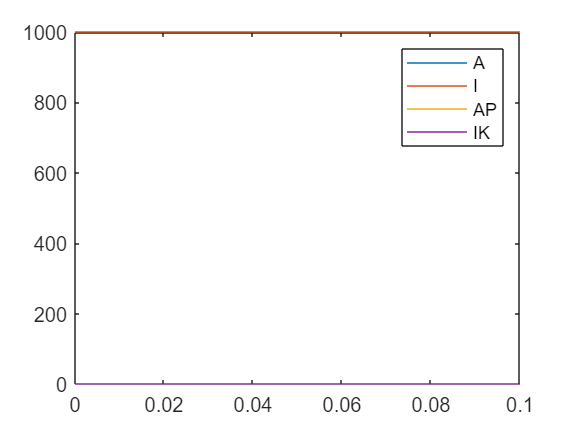

% Ktot = 10;
% Ptot = 10;

KAon = 10;
KAoff = 10;
KAcat = 100;
KIcat = 10;
KIon = 10;
KIoff = 10;

Tot = 500;
tots = 1:1:500;
spoon = zeros(4,length(tots));
ratios = zeros(1,length(tots));
for i = 1:length(tots)
    x = tots(i);
    Ptot = x;
    Ktot = Tot - x;
    ratios(i) = log(Ktot/Ptot);

    dAdt = @(A, I, AP, IK) -KAon*(Ptot-AP)*(A) + KAoff*(AP) + KAcat*(IK);
    dIdt = @(A, I, AP, IK) -KIon*(Ktot-IK)*(I) + KIoff*(IK) + KIcat*(AP);
    dAPdt = @(A, I, AP, IK) KAon*(Ptot-AP)*(A) - KAoff*(AP) - KIcat*(AP);
    dIKdt = @(A, I, AP, IK) KIon*(Ktot-IK)*(I) - KIoff*(IK) - KAcat*(IK);
    
    [T, X] = ode45(@(t,x)[ ...
        dAdt(x(1),x(2),x(3),x(4)); ...
        dIdt(x(1),x(2),x(3),x(4)); ...
        dAPdt(x(1),x(2),x(3),x(4)); ...
        dIKdt(x(1),x(2),x(3),x(4))], ...
        [0,.1], [0.0,1000.0,0.0,0.0]);
    spoon(1, i) = X(end,1)/(X(end,1)+X(end,2));
end
plot(T,X);
legend("A","I","AP","IK");

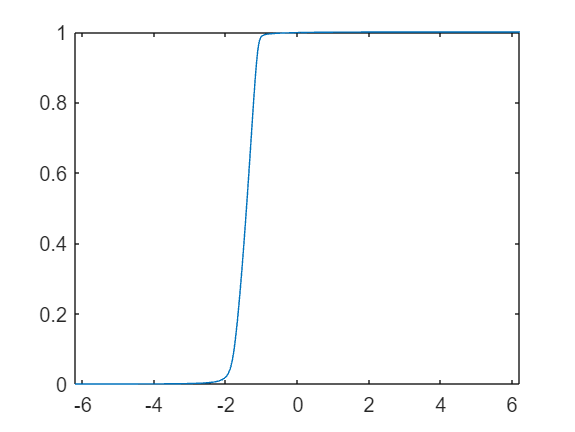

spoon(1,:);
ratios;
plot(ratios,spoon(1,:));